 Loading the battery dataset

%% STEP 1: Download and Load Battery Dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

%% STEP 2: Parse and Segment Data
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable = 'Voltage';
bParser.TimeVariable = 'DateTime';
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  
segmentedRawDataTable = segmentData(bParser);

%% STEP 3: Extract All Valid "Charge" Data for Cycle 1
chargingData = segmentedRawDataTable(...
    segmentedRawDataTable.Cycle_Index == 1 & ...
    segmentedRawDataTable.CyclingPhases == "Charge", :);
chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));

## Compute the rate of voltage change

This quantifies the charging profile numerically  rather than just eyeballing the plot.

% Assumes t (time in seconds) and V (voltage) already extracted, e.g.:
t = chargingData.TimeInSeconds;
V = chargingData.Voltage;

vMax = 3.6;

% --- Identify time interval of 100% charge ---
i100 = find(V >= vMax, 1);
t100 = t(i100);
v100 = V(i100);

% --- Restrict analysis window to start-of-charge through 100% point ---
tPlot = t(1:i100);
vPlot = V(1:i100);

% --- Compute the rate of voltage change (dV/dt) across the whole window ---
% gradient() gives a numerical derivative at every sample point using
% central differences (forward/backward at the endpoints).
dVdt = gradient(vPlot, tPlot);

% --- Identify time interval of 80% charge ---
v80Target = 0.80 * vMax;
i80 = find(vPlot >= v80Target, 1);
t80 = tPlot(i80);
v80 = vPlot(i80);          % actual voltage at/just past the 80% mark

% --- Identify time interval of 50% charge ---
v50Target = 0.50 * vMax;
i50 = find(vPlot >= v50Target, 1);
t50 = tPlot(i50);
v50 = vPlot(i50);

% --- Identify direction-change points (e.g., CC -> CV transition, noise) ---
% diff(sign(dVdt)) ~= 0 flags where the slope of V(t) flips sign
iDC = find(diff(sign(dVdt)) ~= 0) + 1;
tDC = tPlot(iDC);
vDC = vPlot(iDC);

% --- Compute dV/dt AT each key point of interest ---
dVdt_50  = dVdt(i50);
dVdt_80  = dVdt(i80);
dVdt_100 = dVdt(i100);

% --- Display a summary table of rate of voltage change at each interval ---
keyPointNames = {'50% Charge'; '80% Charge'; '100% Charge'};
keyTimes      = [t50; t80; t100];
keyVoltages   = [v50; v80; v100];
keyRates      = [dVdt_50; dVdt_80; dVdt_100];

summaryTable = table(keyPointNames, keyTimes, keyVoltages, keyRates, ...
    'VariableNames', {'ChargeLevel','Time_s','Voltage_V','dVdt_V_per_s'});

disp('--- Rate of Voltage Change at Key Charging Intervals ---')

--- Rate of Voltage Change at Key Charging Intervals ---


disp(summaryTable)

      ChargeLevel      Time_s    Voltage_V    dVdt_V_per_s
    _______________    ______    _________    ____________

    {'50% Charge' }         0     2.0326         0.70662  
    {'80% Charge' }    2.6823     2.8826        0.048187  
    {'100% Charge'}    1246.5     3.6004       0.0014743  




fprintf('\nNote: dV/dt is highest early in charging (steep CC ramp) and\n')


Note: dV/dt is highest early in charging (steep CC ramp) and


fprintf('decreases toward 0 as the battery approaches full charge (CV taper).\n')

decreases toward 0 as the battery approaches full charge (CV taper).


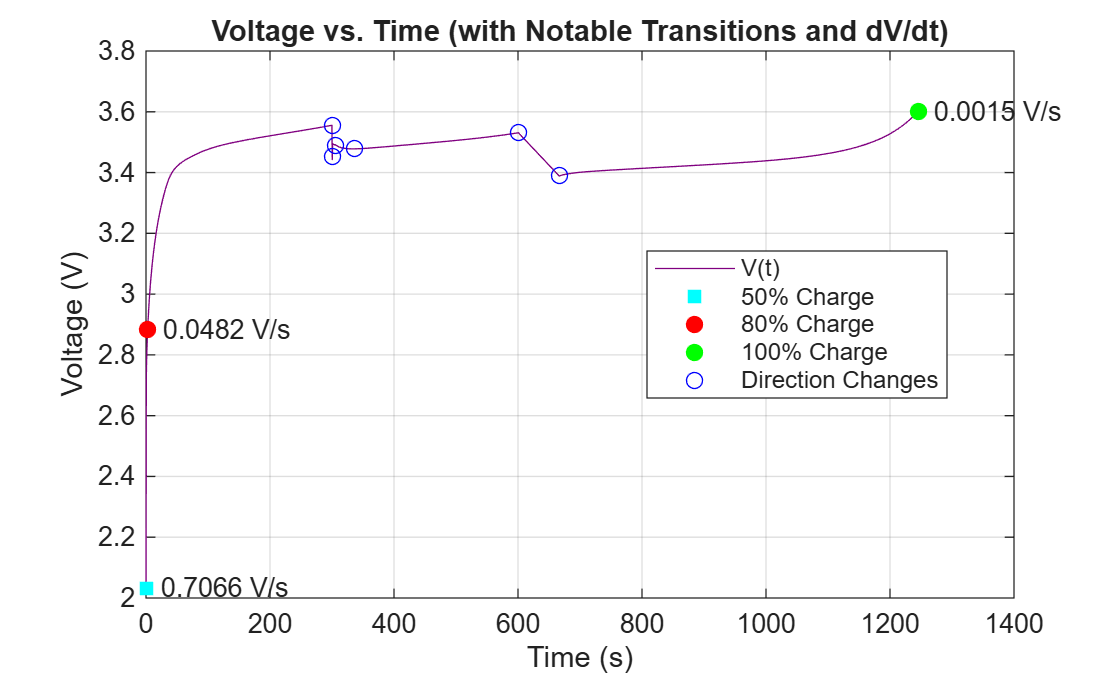


%% Optional: Plot notable transitions, annotated with their dV/dt values
figure('Name', 'Task 3.1');
plot(tPlot, vPlot, 'Color', [0.5, 0, 0.5]);
hold on;

plot(t50,  v50,  'cs', 'MarkerFaceColor', 'c');
plot(t80,  v80,  'ro', 'MarkerFaceColor', 'r');
plot(t100, v100, 'go', 'MarkerFaceColor', 'g');
plot(tDC,  vDC,  'bo');

% Annotate each key point with its instantaneous dV/dt value
text(t50,  v50,  sprintf('  %.4f V/s', dVdt_50));
text(t80,  v80,  sprintf('  %.4f V/s', dVdt_80));
text(t100, v100, sprintf('  %.4f V/s', dVdt_100));

title('Voltage vs. Time (with Notable Transitions and dV/dt)');
xlabel('Time (s)');
ylabel('Voltage (V)');
legend('V(t)', '50% Charge', '80% Charge', '100% Charge', ...
    'Direction Changes', 'Location', 'best');
grid on;
box on;
hold off;